%{
ES115 Streetlight brightness model problem
 originally from Module 1 project bank.pdf - 02/02/2026
Author: Gracy Sylvestre
Version: 1.0
Date: 2026-03-30
State the problem (Purpose):
Brightness along a road is modeled by a quadratic that peaks at the light position. Create two
brightness models for two different streetlights










Describe input values (Knowns)and required output (Unknowns) 
    Input:
        - see description below
    Output:
        - See descriptions below
     
  Engineering Workflow and Algarithems:
    - Setup equations
    - Create coefficient matrix
    - Solve matrix  
    - Test answers 

MATLAB tools/functions:
    - MATLAB inv function 
    - Matrix Left Devision or Gauss elimination method. 
    - Matrix reducced row echelon function. 
    - MATLAB Try function to manage unexpected errors.  

%}

% Task 1: define brightness model in vertex form

%B(x) = -k*(x-h)^2 + Bmax   % Bmax: maximum brightness under streetlight

% Task 2: Create two streetlight models with different locations/Bmax

%streetlight 1 values
k1 = 0.7;   % streetlight 1 fall off
h1 = 4;    % horizontal axis location of streeghtlight 1
Bmax1 = 80; % streetlight 1 max brightness

%streetlight 2 values
k2 = 0.9;   % streetlight 1 fall off
h2 = 6;    % horizontal axis location of streeghtlight 1
Bmax2 = 100; % streetlight 1 max brightness


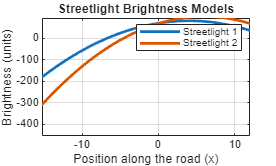

% Task 3: evaluate on domain a plot both streetlights on one figure

x = -20 : 0.5: 20;  % section in which the brightness will be evaluated

B1 = -k1 * (x - h1).^2 + Bmax1;  % Brightness model for streetlight 1
B2 = -k2 * (x - h2).^2 + Bmax2;  % Brightness model for streetlight 2

%plot both models on figure
figure;
plot(x, B1, 'LineWidth', 2); hold on;
plot(x, B2, 'LineWidth', 2);
xlabel('Position along the road (x)');
ylabel('Brightness (units)');
title('Streetlight Brightness Models');
legend('Streetlight 1', 'Streetlight 2');
grid on;

% Task 4: Identify and compare maxiumum on each brightness curve 